# Plotting Data in Matlab

This notebook will walk you through the generation of impressive matlab plots. If you have questions about matlab syntax, visit [this link](https://www.mathworks.com/help/matlab/?requestedDomain=www.mathworks.com) for documentaion.

This notebook uses an example from a strain gauge lab from last semester.

# Loading data

Your first step is to load data from WaveForms. But before we go any further, we clear all figures and graphics using the command [clf](https://www.mathworks.com/help/matlab/ref/clf.html).

% clears all figures and graphics
clf

You should always save your WaveForms data in the form of a csv (comma separated value) file. MatLab does operations on [matricies and arrays](https://www.mathworks.com/help/matlab/learn_matlab/matrices-and-arrays.html). An array is a collection of values and a matrix is just a two-dimensional array. When you import a csv file into matlab it will save as a matrix.

 Load these files using the function [csvread](https://www.mathworks.com/help/matlab/ref/csvread.html).

% Load data from a file using matrix_name = csvread(filename,R1,C1)
% The R1 and C1 arguments are first rows and columns to import respectively
% You don't have to include these arguments but doing so will let you ingnore the headers at the top of the csv 
csv_data = csvread('suddenLoading.csv');


**Note:** you'll have to delete all non-numerical entries from your csv.

The voltage cvs has three columns: time, voltage from channel 1 of the analog discovery (unfiltered result) and from channel 2 (filtered result). Don't worry about what those mean for now, this is just an exercise in making nice plots given a couple csv's from WaveForms. You can extract the columns from your csv using [indexing](https://www.mathworks.com/company/newsletters/articles/matrix-indexing-in-matlab.html).

% Extract the columns of your csv using the format matrix(row, column)
% ':' means to select every row/column in the selected column/row
time = csv_data(:,1);
channel1 = csv_data(:,2);
channel2 = csv_data(:,3);

**Note: **In MatLab, the result of every line will print unless you include a semicolon which suppresses the result. The line will run but not print out.

# Mathematical Operations

The next step in any lab after getting your data is processing it or doing some sort  of mathematical operation on it. Operations in MatLab are [martix- or array-wide](https://www.mathworks.com/help/matlab/matlab_prog/array-vs-matrix-operations.html). This means that when you do a scalar operation to a matrix or array, you do that same scalar operation to every item in the matrix or array.

% Time in our data starts at -.083 seconds, we want to add .083 to every item
% in our time array so time starts at 0 seconds instead
time = time + .083;

time =    -0.7470
   -0.7468
   -0.7465
   -0.7463
   -0.7460
   -0.7458
   -0.7455
   -0.7453
   -0.7450
   -0.7448



% Say we know the the resistence byetween channel 1 and channel 2 is 1K Ohm
% We'd calculate the current like so...(this is a completely made-up example)
current = (channel1 - channel2)./1000;

current =    1.0e-04 *

   -0.0321
   -0.2125
   -0.2193
   -0.2260
   -0.2193
   -0.2192
   -0.2058
   -0.2125
   -0.2058
   -0.2226


**Note:** whenever you're doing matrix-wide division, mutliplication, or exponentionals, **always** put a period before the operations (e.g. './' or '.^').

# Plots and Subplots

To plot multiple plots on one figure, use a few [subplot](https://www.mathworks.com/help/matlab/ref/subplot.html) statements. sublot(m, n, p) divides the figure into an m-by-n grid, p denotes a plot number (first plot is first row first column, second plot is first row, second column, etc.)

% This subplot is a 2 by 1 grid
% include a subplot statement for each subplot
% everything after one subplot statement but before the next makes up that subplot

% Define the first subplot
subplot(2,1,1)

For plotting 2D data on a normal axis, use the [plot](https://www.mathworks.com/help/matlab/ref/plot.html) function. For logaritmic plots, use the [loglog](https://www.mathworks.com/help/matlab/ref/loglog.html), [semilogx](https://www.mathworks.com/help/matlab/ref/semilogx.html), or [semilogy](https://www.mathworks.com/help/matlab/ref/semilogy.html) function. For scatter plots us.e the [scatter](https://www.mathworks.com/help/matlab/ref/semilogy.html) function. Right after plotting, usd the [hold on ](https://www.mathworks.com/help/matlab/ref/hold.html)statement to return the current axes and plots

**Note: **when plotting on a logaritmic scale, call hold on after your call too loglog, semilogx, or semilogy. Otherwise MatLab will try to plot your data on a non-logarithmic scale. 

    % plot current vs. time
    plot(time, current)
    % Set title and x- and y-axis labels
    title(['Current after Sudden Loading'])
    xlabel('Time (s)')
    ylabel('Current (amps)')

subplot(2,1,2)
    % (still under subplot(2,1,1), indented for clarity)
    % plot channel1 voltage vs time with a red line
    plot(time, channel1, 'r')
    hold on
    % plot channel2 voltage vs. time with a blule line
    plot(time, channel2, 'b')
    % Set title and x- and y-axis labels
    title(['Voltage after Sudden Loading'])
    xlabel('Time (s)')
    ylabel('Voltage (V)')

If you plot multiple data sets on one plot, you can include a [lengend](https://www.mathworks.com/help/matlab/ref/legend.html).

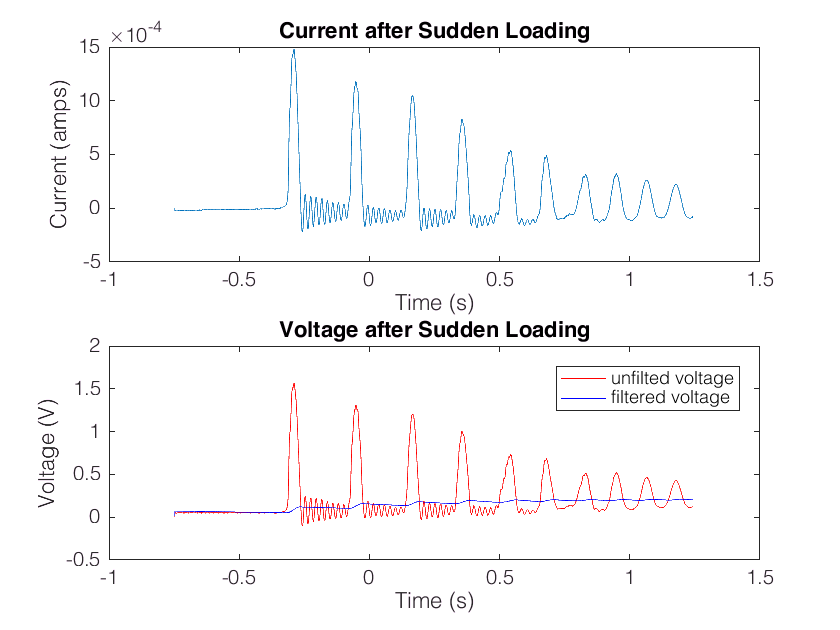

ans =   Legend (unfilted voltage, filtered voltage) with properties:

         String: {'unfilted voltage'  'filtered voltage'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6613 0.3480 0.2196 0.0710]
          Units: 'normalized'

  Show all properties


    legend('unfilted voltage','filtered voltage')'

# Exporting Figures

In the live notebook, double click on the figure to view it in its own screen. Then choose File >> Save As and save your figure.

**Tip:** save your figure as an EPS (Encapsulated Postscript Vector) file so it doesn't pixelate. 

# And you're done!

This MatLab Live Script was created by Sophia Nielsen. Feedback or questions? Email sophia@students.olin.edu.